DFT umschreiben

36 Frequenzen gesucht

beginnt bei Taste d 30 = 146,83 Hz

endet bei 65 = 1108,73 Hz

0,1 Sekunden Refresh-Rate

Amplitude aus Farbe mappen

Farben von Blau bis Rot

Blau, wenn Frequenz keine Amplitude hat / Ruhezustand

numberOfKeys = 36;
refreshRate = 0.1;
key_min = 30;
key_max = 30 + 36 - 1;

[y, Fs] = audioread("frequenztest.wav");
x = (1:length(y))/Fs;
%plot(x, y);

n = Fs * 0.1;
l = floor(length(y) / n);
result = zeros(36, l);
minY = 0;
maxY = 0;
for i = 0:l
    y_part = y((n * i) + 1: n * (i + 1));
    Y = newDFT(y_part, key_min, key_max);
    result(1:36, i+1) = abs(Y);
end

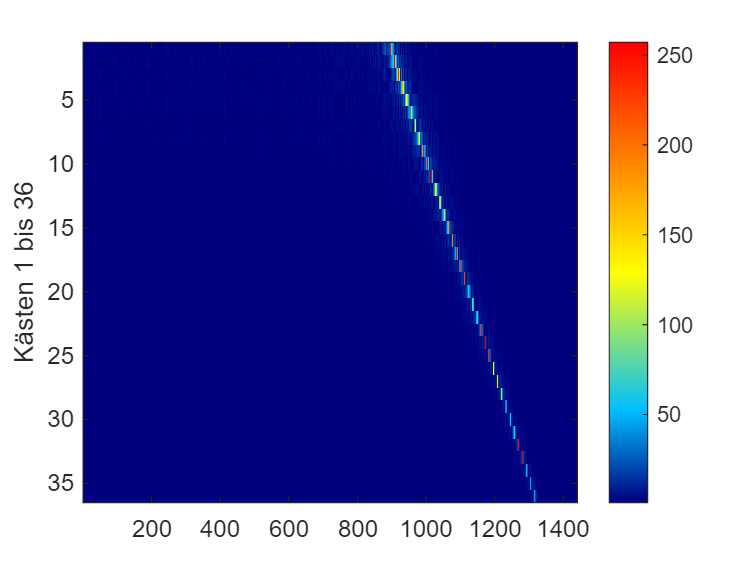

maxAmp = max(max(result));
minAmp = min(min(result)); % min = 0

darkBlue = [0, 0, 0.5];
lightBlue = [0, 0.75, 1];
yellow = [1, 1, 0];
red = [1, 0, 0];

customColormap = [darkBlue; lightBlue; yellow; red];
customColormap = interp1([0, 0.2, 0.5, 1], customColormap, linspace(0, 1, 256));

image(result);
colorbar;
colormap(customColormap);
ylabel("Kästen 1 bis 36");